Rocket ODE simulation based on the Falcon 9 Rocket

startingAngle   = 0.058;      %[°]
tiltingTime     = 7.5;       %[s]
odeset('AbsTol',1e-6, 'RelTol',1e-6 );

% goal 800km +-100km with v = 7.4555 km / s +- 0.05 m/s


Staging data:

Payload

payload = 9500; %[kg]

Last Stage

stage2      = struct;
stage2.t    = 397;          % [s]    burn time
stage2.mp   = 111.5e+03;      % [kg]
stage2.ms   = 4.5e+03;        % [kg]
stage2.A    = 10.75;        % [m^2]  front area
stage2.Isp = 354;         % [m/s]
stage2.m0   = stage2.ms + stage2.mp + payload;        %[kg]   starting mass
stage2.mf   = stage2.ms + payload;                    %[kg]   final mass

stage2.dm   = stage2.mp / stage2.t;
stage2.T    = stage2.Isp * 9.81 * stage2.dm

stage2 = struct with fields:
      t: 397
     mp: 111500
     ms: 4500
      A: 10.7500
    Isp: 354
     m0: 125500
     mf: 14000
     dm: 280.8564
      T: 9.7534e+05


Starting Stage

stage1      = struct;
stage1.t    = 162;          % [s]    burn time
stage1.mp   = 381e+03;      % [kg]
stage1.ms   = 57.2e+03;      % [kg]
stage1.A    = 10.75;        % [m^2]  front area
stage1.Veff = 3200;         % [m/s]
stage1.m0   = stage1.ms + stage1.mp + stage2.m0; %[kg]   starting mass
stage1.mf   = stage1.ms + stage2.m0;            %[kg]   final mass

stage1.dm   = stage1.mp/stage1.t;
stage1.T    = stage1.Veff * stage1.dm

stage1 = struct with fields:
       t: 162
      mp: 381000
      ms: 57200
       A: 10.7500
    Veff: 3200
      m0: 563700
      mf: 182700
      dm: 2.3519e+03
       T: 7.5259e+06


Let's get Launching!

First two seconds (streight up):

u0      = [0; pi/2; 0; 0; stage1.m0];
tSpan   = [0, tiltingTime];

[t1, uOut] = ode45(@(t,u) rocketODEfixed(u,stage1, pi/2),tSpan,u0);

v1      = uOut(:,1); v1(end) 

ans = 28.0768

gamma1  = uOut(:,2); gamma1(end)

ans = NaN

x1      = uOut(:,3); x1(end)

ans = 6.3236e-15

h1      = uOut(:,4); h1(end)

ans = 103.2734

m1      = uOut(:,5); m1(end)

ans = 5.4606e+05

t1(end)

ans = 7.5000

Now lets add a tiny change in Angle!

gammaStart = pi/2 - pi*startingAngle/180;

u1      = [v1(end); gammaStart; x1(end); h1(end); m1(end)];
tSpan   = [t1(end), stage1.t];

[t2, uOut] = ode45(@(t,u) rocketODE(u,stage1),tSpan,u1);

v2      = uOut(:,1); v2(end) % should be 1.515km/s

ans = 2.0598e+03

gamma2  = uOut(:,2); gamma2(end)

ans = 1.1339

x2      = uOut(:,3); x2(end)

ans = 3.4202e+04

h2      = uOut(:,4); h2(end)

ans = 1.0396e+05

m2      = uOut(:,5); m2(end)

ans = 1.8270e+05

t2(end)

ans = 162

And now the second! This time with the steering law included

For this, lets first accumulate the relevatn steering data!

steeringData            = struct;
steeringData.gamma0     = gamma2(end);
steeringData.tStart     = t2(end);
steeringData.tEnd       = t2(end) + stage2.t;

And now run it!

u2      = [v2(end); gamma2(end); x2(end); h2(end); stage2.m0];
tSpan   = [t2(end), stage2.t + t2(end)];


[t3, uOut] = ode45(@(t,u) rocketODEend(u,stage2,t, steeringData),tSpan,u2);

v3      = uOut(:,1); v3(end) % Should be around 8 km/s

ans = 7.4667e+03

gamma3  = uOut(:,2); gamma3(end)

ans = 0.0054

x3      = uOut(:,3); x3(end)

ans = 9.3739e+05

h3      = uOut(:,4); h3(end)

ans = 7.7478e+05

m3      = uOut(:,5); m3(end)

ans = 1.4000e+04

t3(end)

ans = 559

stageCoast      = struct;
stageCoast.t    = 10000;    %[s]    burn time
stageCoast.m0   = m3(end);
stageCoast.mf   = m3(end);  %[kg]   starting mass
stageCoast.A    = stage2.A; %[m^2]  front areae
stageCoast.dm   = 0;
stageCoast.T    = 0;

u3      = [v3(end); gamma3(end); x3(end); h3(end); stageCoast.m0];
tSpan   = [t3(end), stageCoast.t + t3(end)];

[t4, uOut] = ode45(@(t,u) rocketODE(u,stageCoast),tSpan,u3);


v4      = uOut(:,1);% Should be around 8 km/s
gamma4  = uOut(:,2);
x4      = uOut(:,3);
h4      = uOut(:,4);
m4      = uOut(:,5);

All the simulations are done! Lets get some plots :)

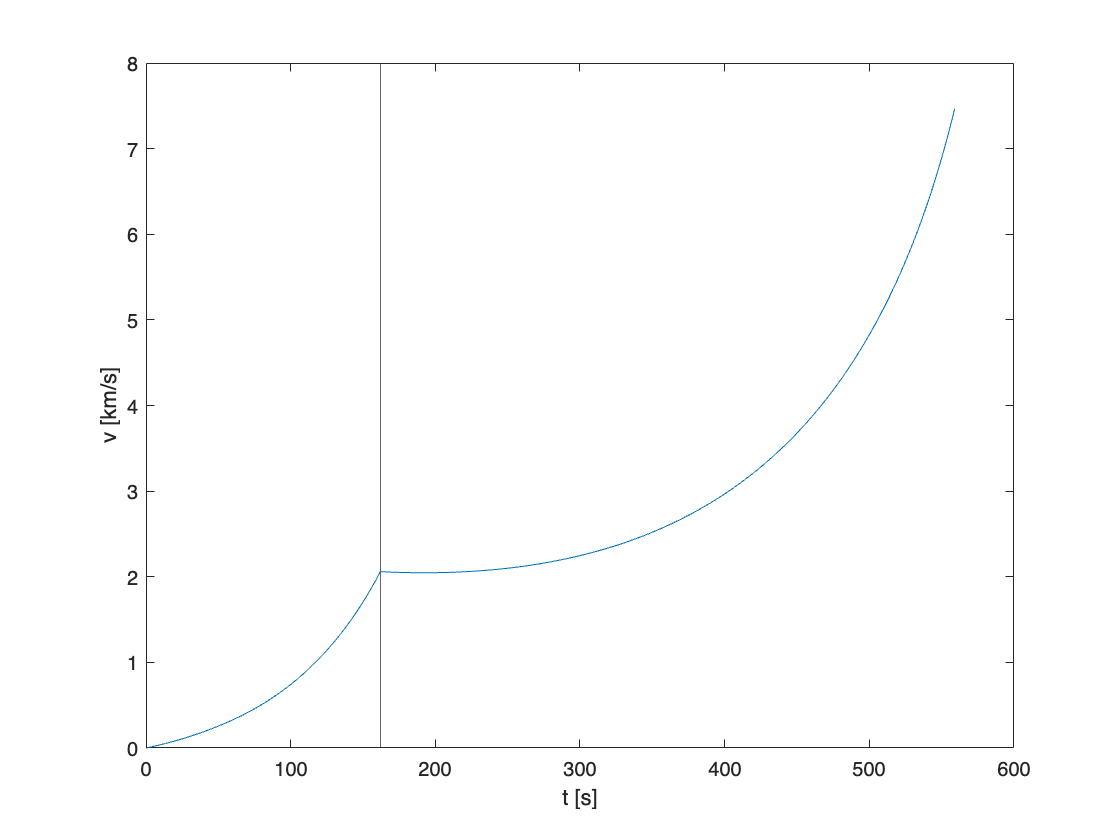

t = [t1; t2; t3 ]; %t4];
v = [v1; v2; v3 ]; %v4];
x = [x1; x2; x3 ]; %x4];
h = [h1; h2; h3 ]; %h4];
gamma = [gamma1; gamma2; gamma3 ];% gamma4];
m = [m1; m2; m3 ]; %m4];
save trajectory.mat t v x h m gamma

figure
plot(t, v/1000)
xline(stage1.t)
xlabel("t [s]")
ylabel("v [km/s]")

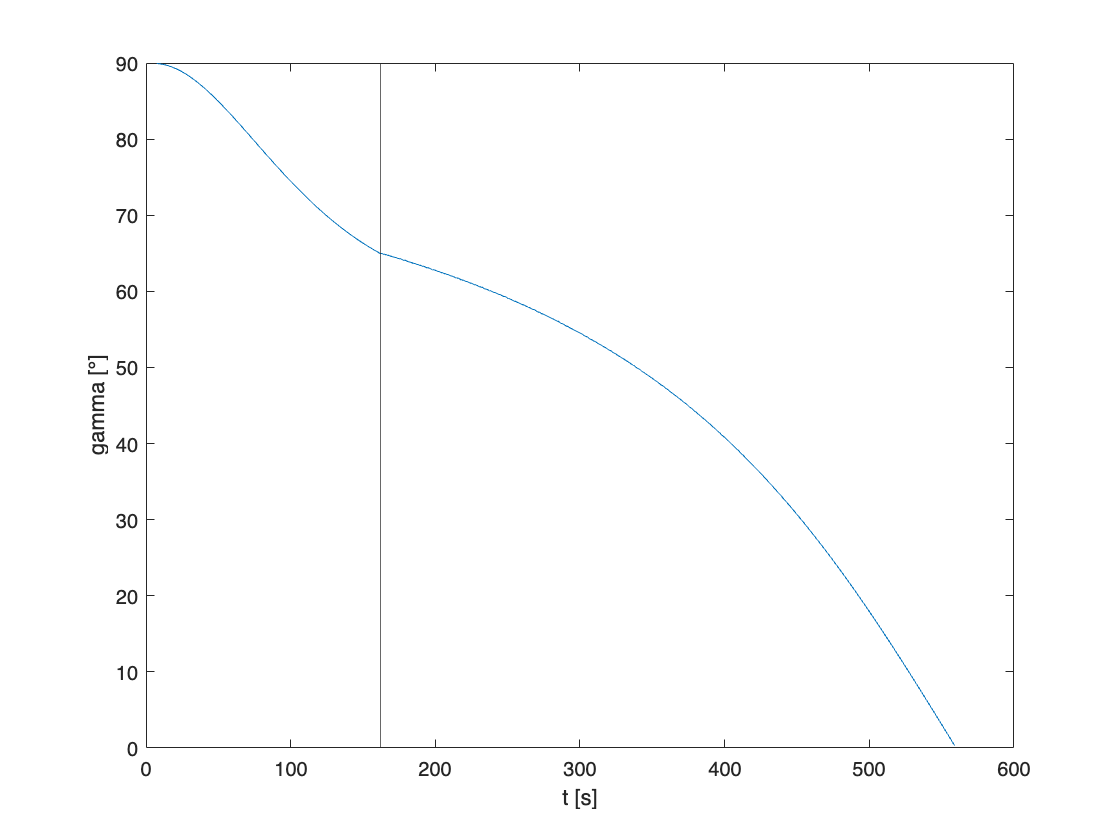


figure
plot(t, gamma/pi*180)
xline(stage1.t)
xlabel("t [s]")
ylabel("gamma [°]")

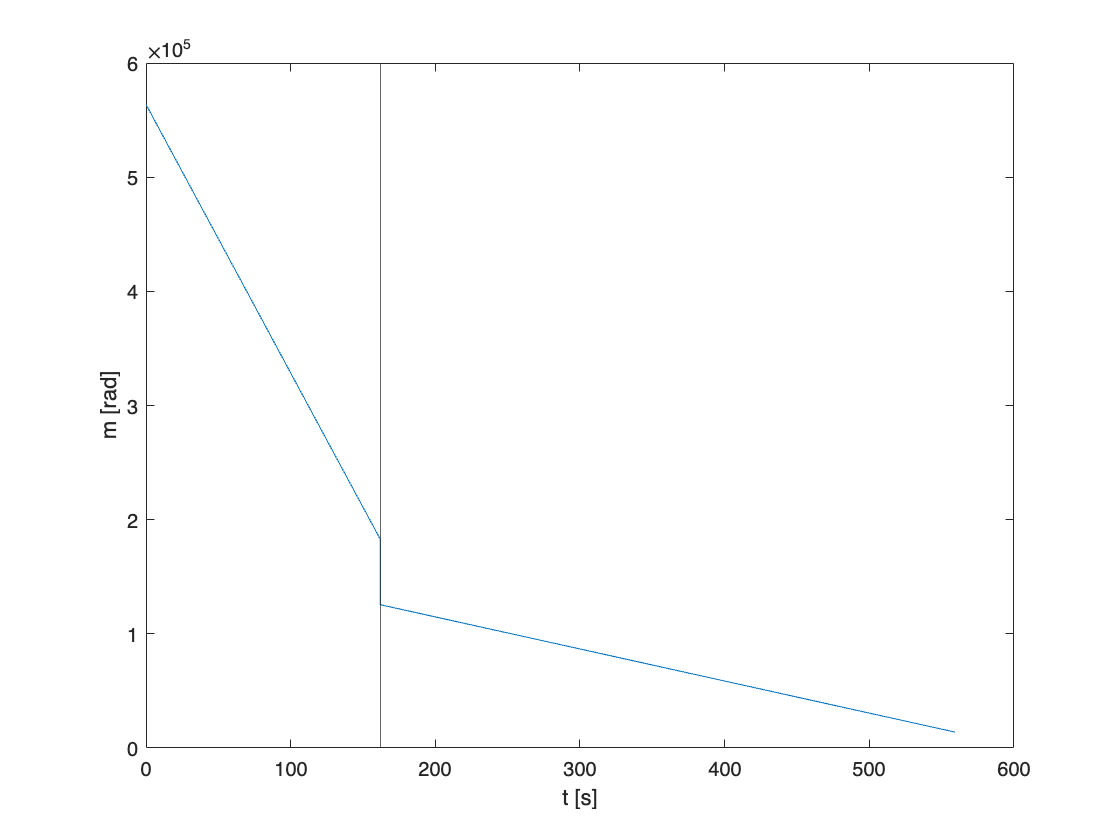



figure
plot(t, m)
xline(stage1.t)
xlabel("t [s]")
ylabel("m [rad]")

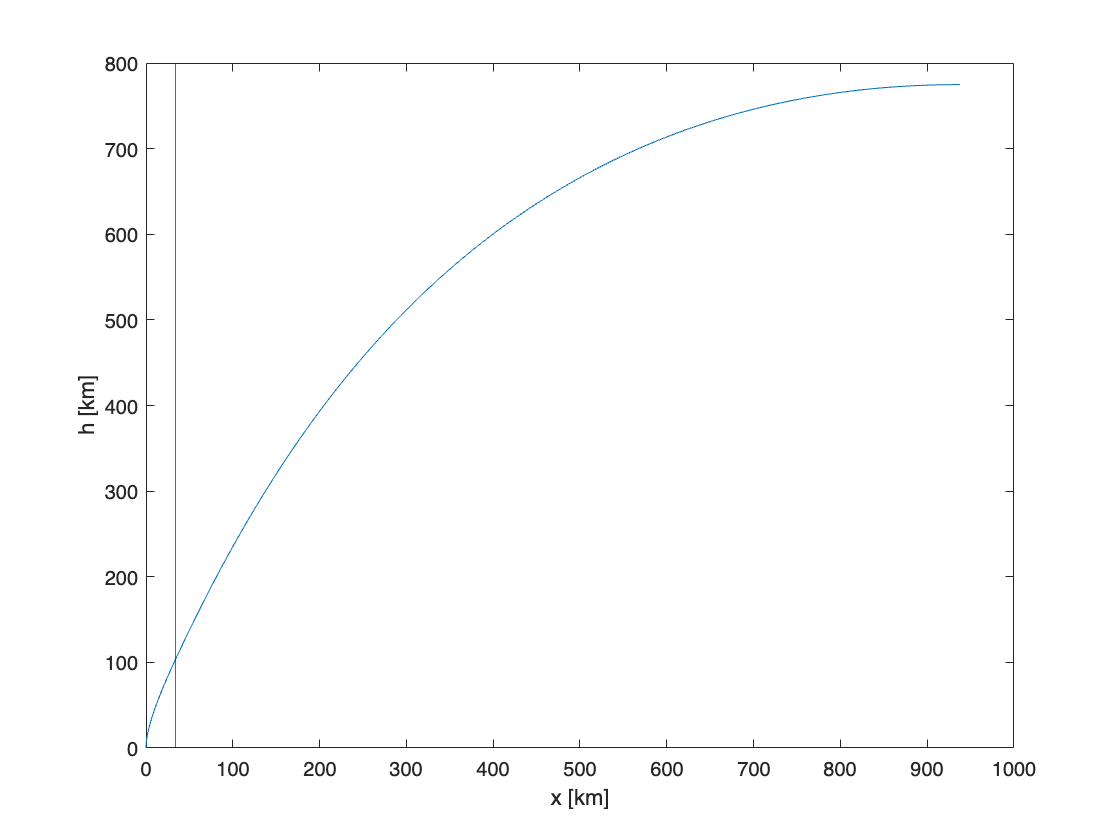


figure
plot(x/1000, h/1000)
xline(x2(end)/1000)
xlabel("x [km]")
ylabel("h [km]")